# Initialize

all_railtrack_imgs = Read_Images('images/Railway', '*.jpg');

Reading images at - images\Railway\*.jpg
Number of images found in directory: 6
Read 6/6


%good_railtrack_imgs = Read_Images('images/Railway', '*good*.jpg');
%bad_railtrack_imgs = Read_Images('images/Railway', '*bad*.jpg');
temp_img = all_railtrack_imgs{1};

nr_of_images = length(all_railtrack_imgs);
show_img_index = 1;

% Resize images for memory purposes
for i = 1:nr_of_images
    all_railtrack_imgs{i} = imresize(all_railtrack_imgs{i}, 0.5);
end

## Color Segmentation

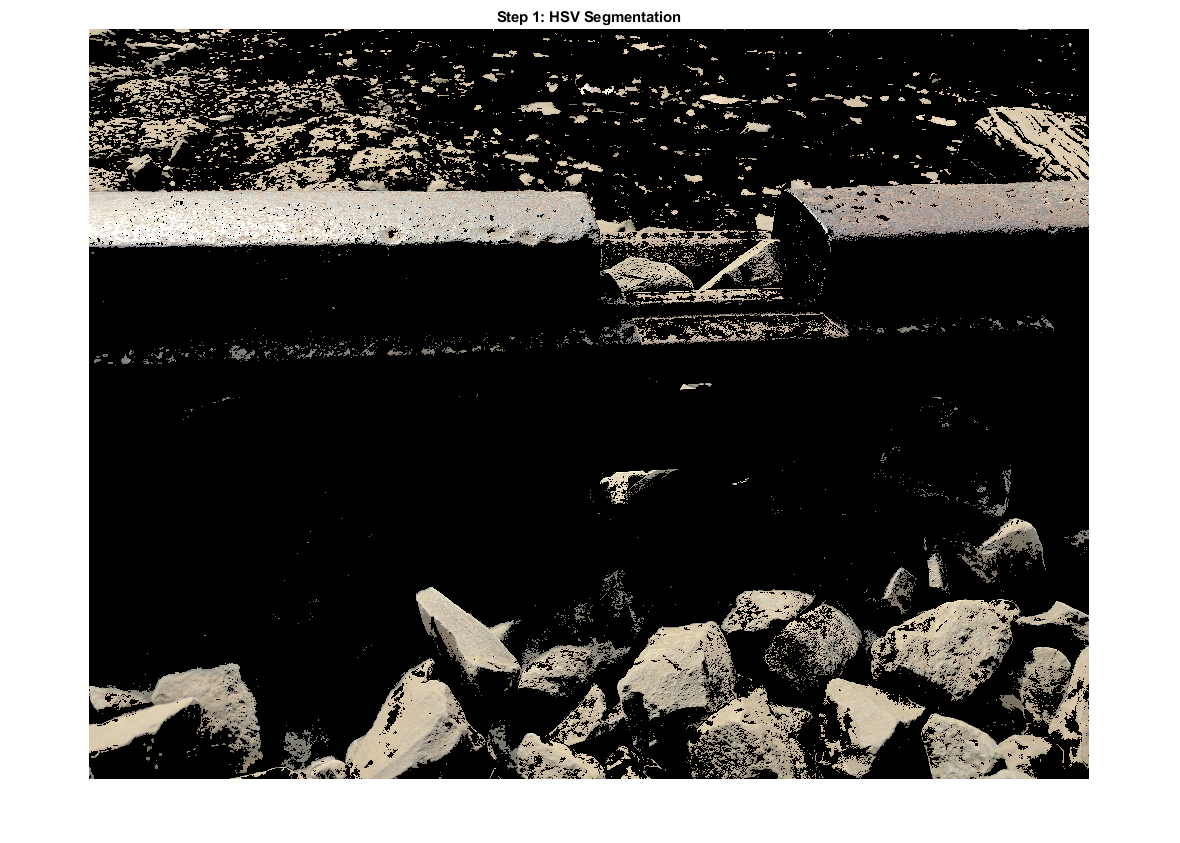

figure;
color_railtrack_all = {0};
for i = 1:nr_of_images
    img = all_railtrack_imgs{i};
    [BW, maskedRGBImage] = createMask(img);
    
    color_railtrack_all{i} = maskedRGBImage;
end
imshow(color_railtrack_all{show_img_index});
title("Step 1: HSV Segmentation");

## Grayscale Conversion

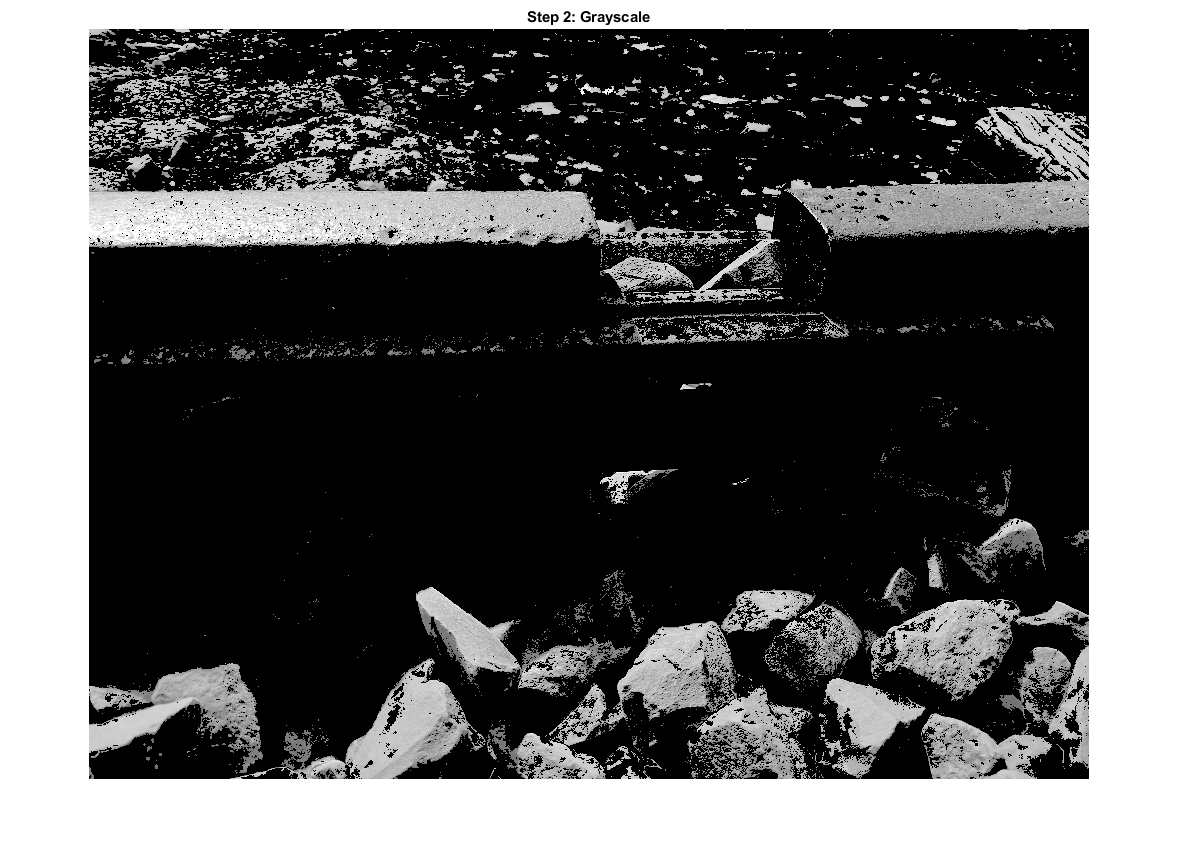

figure;
gray_railtrack_all = {0};
for i = 1:nr_of_images
    gray_railtrack_all{i} = rgb2gray(color_railtrack_all{i});
end
imshow(gray_railtrack_all{show_img_index});
title("Step 2: Grayscale");

## Contrast Enhancement

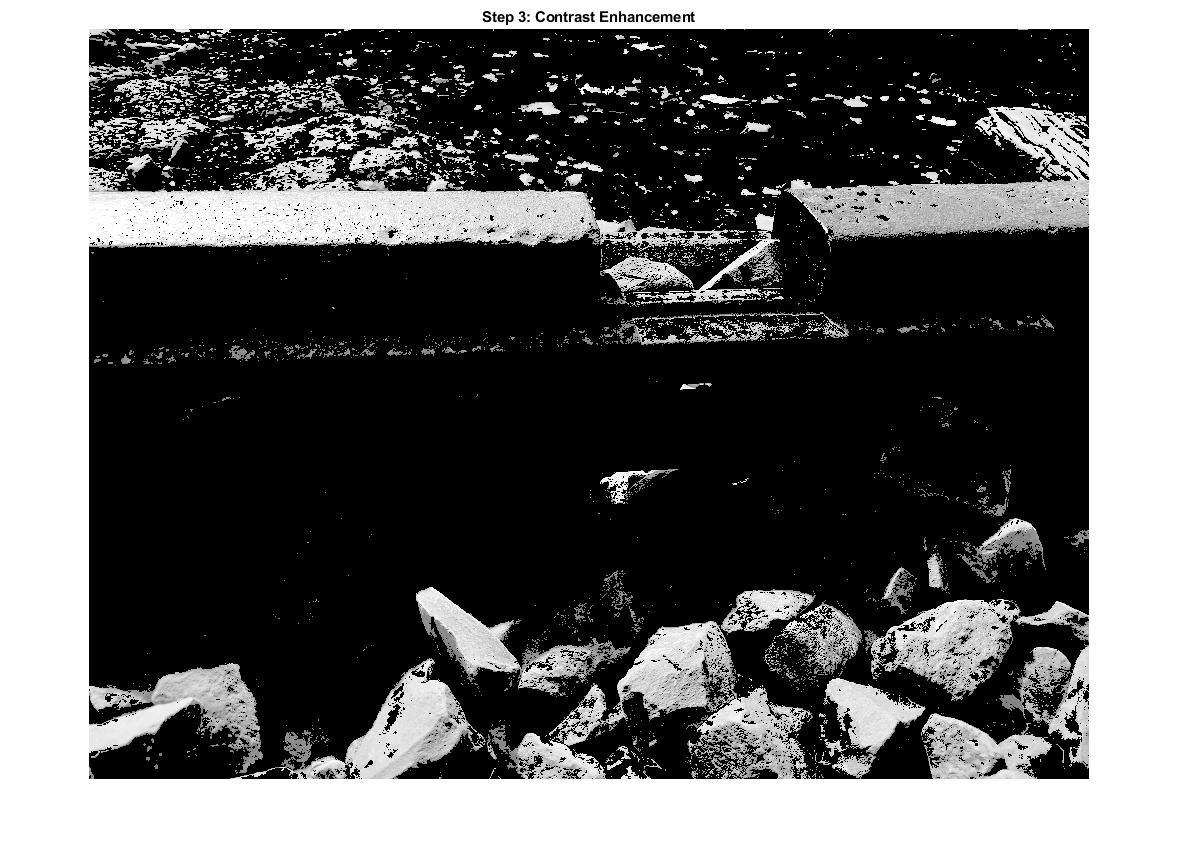

figure;
con_railtrack_all = {0};
for i = 1:nr_of_images
    img = gray_railtrack_all{i};
    
    %img = img * 1.5;
    img = imadjust(img);
    
    % Can't histeq because has black background (TODO: exclude it)
    %img = histeq(img);
    %img = adapthisteq(img);
    
    con_railtrack_all{i} = img;
end
imshow(con_railtrack_all{show_img_index});
title("Step 3: Contrast Enhancement");

## Noise & Background Removal

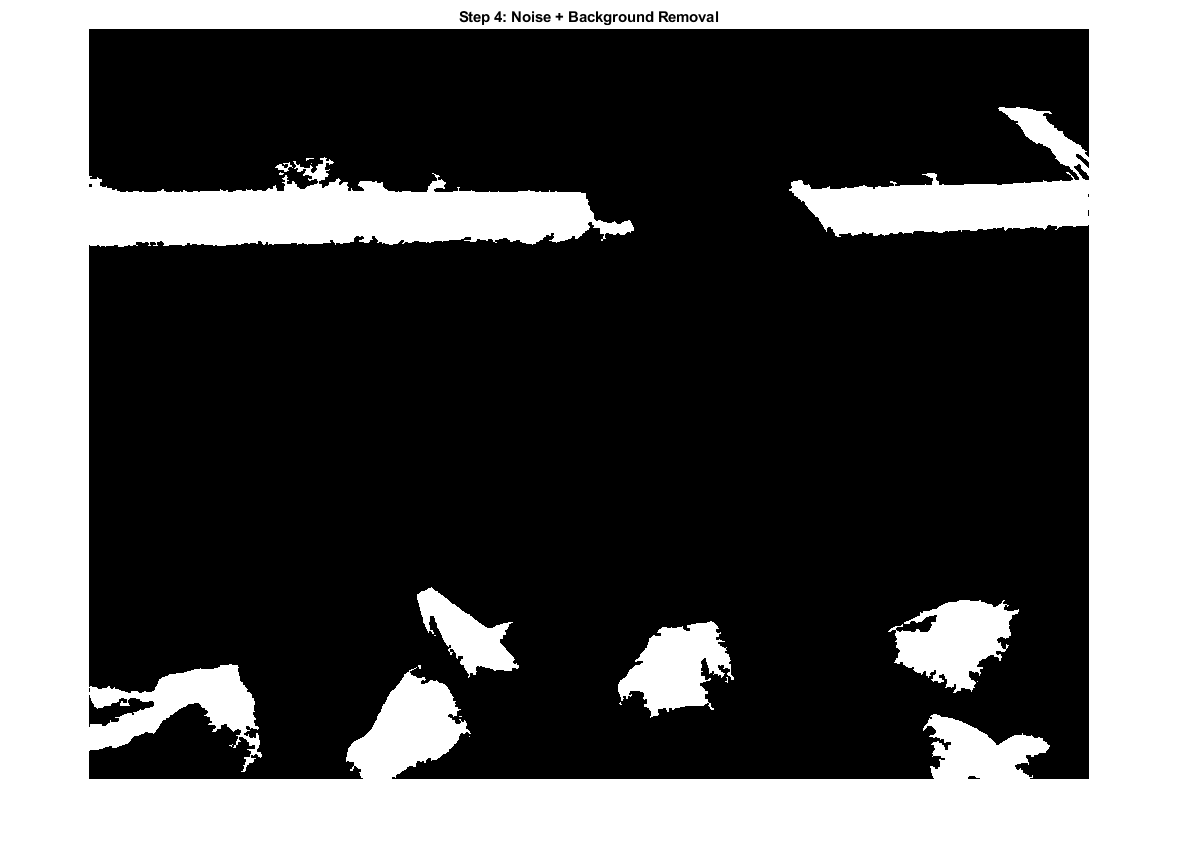

figure;
clean_railtrack_all = {0};
j = 1;
for i = 1: nr_of_images
    
    img = con_railtrack_all{i};
    
    % median filter - it preserves edges the best
    bw_img_median = medfilt2(img);
    
    % erode/dilate
    se_vertical = strel('line', 3, 90);
    se_horizontal = strel('line', 3, 0);
    se_rec_ver = strel('rectangle', [2, 3]);
    se_rec_hor = strel('rectangle', [3, 2]);
    
    %bw_img_open = imopen(bw_img_median, se_rec_ver);
    bw_img_eroded = imerode(bw_img_median, [se_rec_ver, se_rec_hor]);
    % fill holes
    bw_img_filled = imfill(bw_img_eroded, 'holes');
    % remove small objects
    bw_img_cleaned = bwareaopen(bw_img_filled, 15000);
    
    clean_railtrack_all{i} = bw_img_cleaned;
end
imshow(clean_railtrack_all{show_img_index});
title("Step 4: Noise + Background Removal");

## Edge Detection

### Prewitt

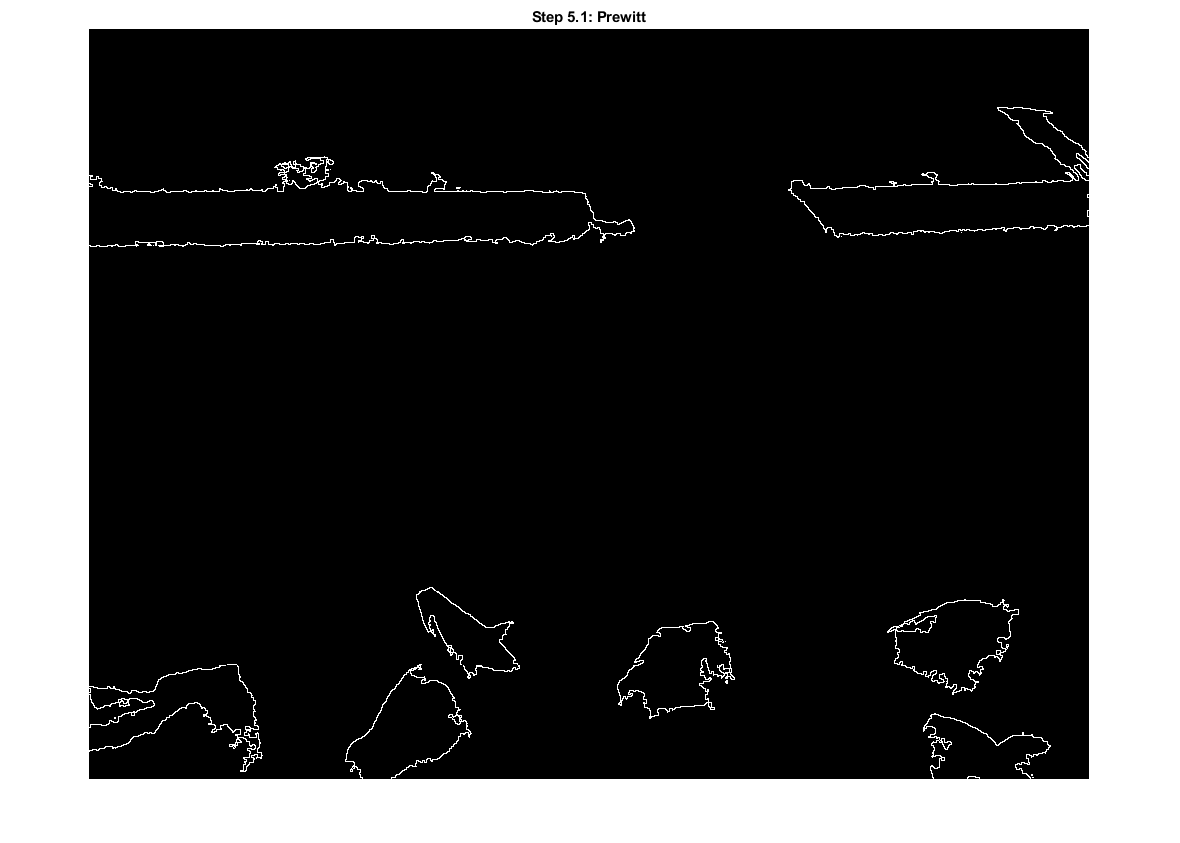

figure;
prewitt_railtrack_all = {0};
for i = 1:nr_of_images
    img = clean_railtrack_all{i};
    
    bw_img = edge(img, 'prewitt', 0.1, "both", "nothinning");
    
    prewitt_railtrack_all{i} = bw_img;
end
imshow(prewitt_railtrack_all{show_img_index});
title("Step 5.1: Prewitt");

### Lapacian of Gaussian

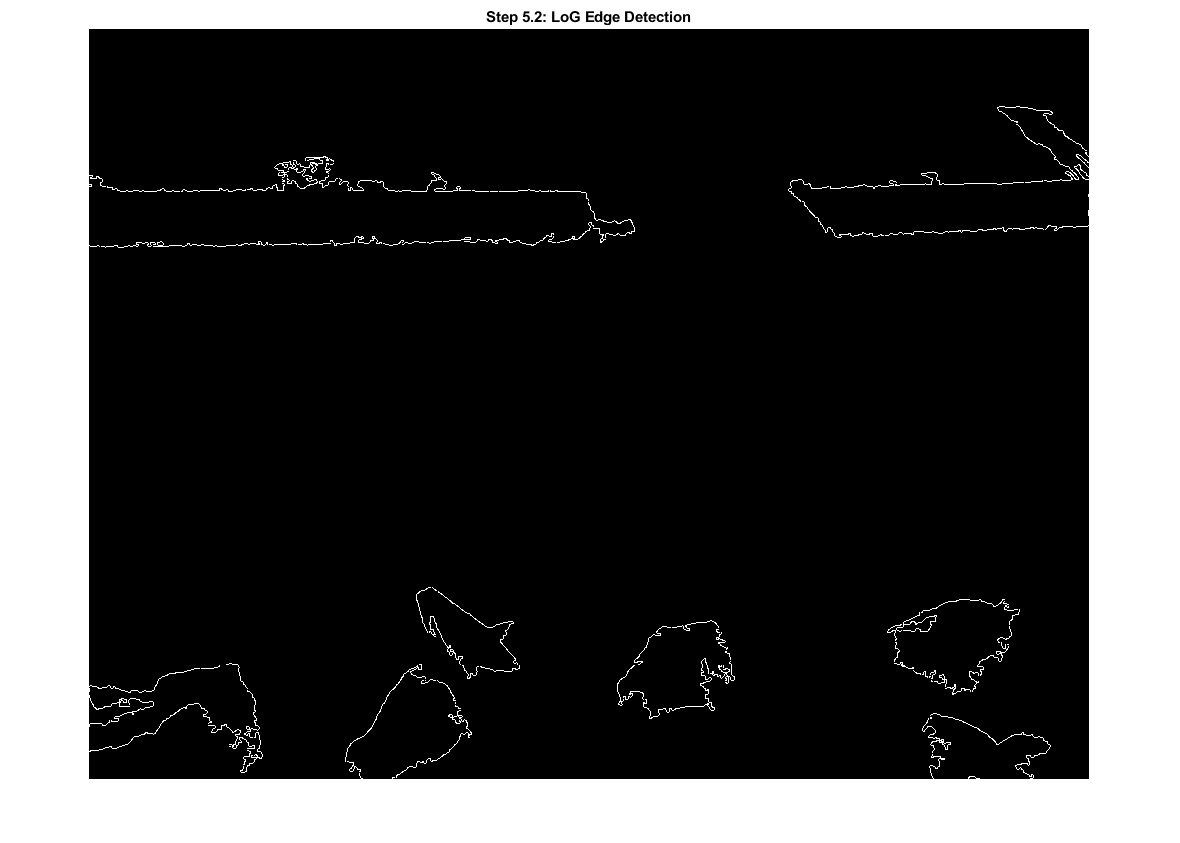

figure;
log_railtrack_all = {0};
for i = 1:nr_of_images
    
    log_img = clean_railtrack_all{i};
    
    % Lapacian %
    %gauss_filter = fspecial('gaussian', [3,3], 0.5);
    %img_lap = imfilter(img, gauss_filter);
    %lap_filter = fspecial('laplacian', 0.5);
    %bw_img = imfilter(img, lap_filter);
    
    % Lapacian of Gaussian %
    %bw_img = edge(img, 'log');
    log_filter = fspecial('log', 5, 0.4);
    bw_img = imfilter(log_img, log_filter);
    
    log_railtrack_all{i} = bw_img;
end
imshow(log_railtrack_all{show_img_index});
title("Step 5.2: LoG Edge Detection");

## Isolation + Quality Determination

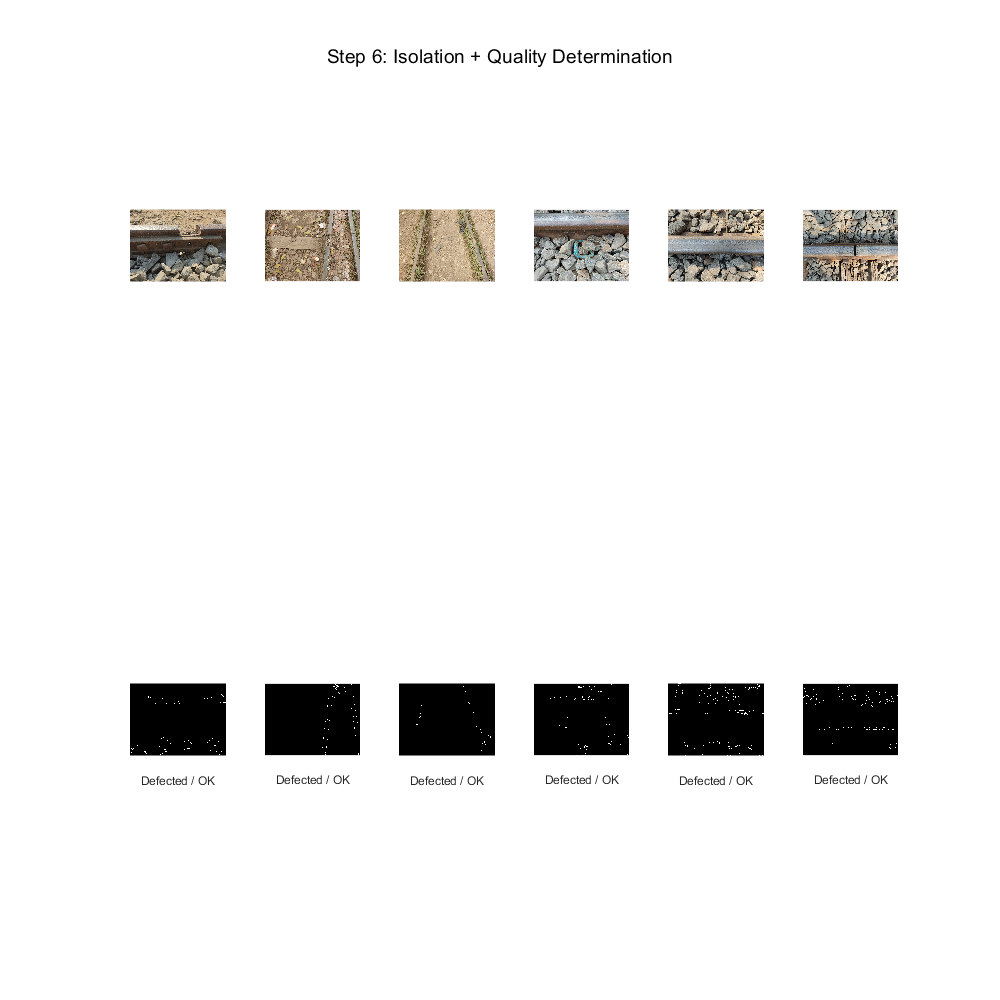

figure('Position', [400, 400, 1000, 1000]);
nr_of_images = length(all_railtrack_imgs);

for i = 1: nr_of_images
    
    bw_img = log_railtrack_all{i};
    
    % TODO: Get line info
    bw_stats = regionprops(bw_img, 'all');
    
    % Hough Transform
    % R = the distance from the origin to the line along a vector perpendicular to the line
    % T = the angle in degrees between the x-axis and this vector
    %[H,T,R] = hough(bw_img,'RhoResolution',0.5,'Theta',-90:0.5:89);
    
    subplot(2, nr_of_images, i);
    imshow(all_railtrack_imgs{i});
    
    subplot(2, nr_of_images, i+nr_of_images);
    imshow(bw_img);
    
    %if ([bw_stats.Orientation] ~= 90)
    %    xlabel("Ok");
    %else 
    %    xlabel("Defected");
    %end
    xlabel("Defected / OK");
end
sgtitle("Step 6: Isolation + Quality Determination");

% Questions %

% 1. Explain the techniques you chose for each step. %

% a. For Color Segmentation I used an HSV color map in order to keep the full
%    range of hues that a railtrack material can be (steel)
% b. Then, I converted the masked image in grayscale and increased its
%    contrast so that the edges of the tracks can be easier to find
% c. For removing the Noise & Background, I 


% 2. State the assumptions you made, like the size of crack to be considered a defect,
% thresholds you used for good/defective track, etc. %

% 3. Does your algorithm work on all images provided? If not, how can you
% improve it? %

% 4. What changes do you need to do to make your application work in poor
% lighting, rain, etc? %